close all
clear
clc

# Padé approximation

Test padé approximation with the signal $x(n)$ defined below.

Test with AR(2) model, AM(2) and ARMA(1,1).

N = 12;
n = 0:N-1;
xn = [1, 3*(0.5).^n(2:end)]

xn =     1.0000    1.5000    0.7500    0.3750    0.1875    0.0938    0.0469    0.0234    0.0117    0.0059    0.0029    0.0015


dn = [1, zeros(1,N-1)];

## 1) Test with AR(2): p=2, q=0

Compute the $X_q$ matrix using the Matlab `convmtx() `function and chose the right index to extract the $X_q$ as in theory eq (4.13)

p=2;
q=0;
xn = xn(:); % make xn vertical
X = convmtx(xn, p+1)

X =     1.0000         0         0
    1.5000    1.0000         0
    0.7500    1.5000    1.0000
    0.3750    0.7500    1.5000
    0.1875    0.3750    0.7500
    0.0938    0.1875    0.3750
    0.0469    0.0938    0.1875
    0.0234    0.0469    0.0938
    0.0117    0.0234    0.0469
    0.0059    0.0117    0.0234



Xq = X(q+2:q+p+1, 2:p+1)

Xq =     1.0000         0
    1.5000    1.0000


Compute the vector $x_{q+1}$ as well:

xq_1 = X(q+2:q+p+1, 1)

xq_1 =     1.5000
    0.7500


And now compute the $a_p$ coefficients:

if det(Xq)
    ap = inv(Xq)*(-xq_1); % pinv is used in case
    ap = [1; ap]
else
    disp('Xq is a singular matrix !')
end 

ap =     1.0000
   -1.5000
    1.5000


Compute the numerator coefficients here is obvious that $b_q(0) = x_n(0)$

X0 = X(1:q+1, 1:p+1)

X0 =      1     0     0


bq = xn(1)

bq = 1

Now compute the impulse response that is $\hat{x}(n) = h(n)$

xhat = impz(bq, ap, length(xn))

xhat =     1.0000
    1.5000
    0.7500
   -1.1250
   -2.8125
   -2.5312
    0.4219
    4.4297
    6.0117
    2.3730


Compute the error of the approximation and the least square error:

Els = norm(xhat-xn)

Els = 15.7206

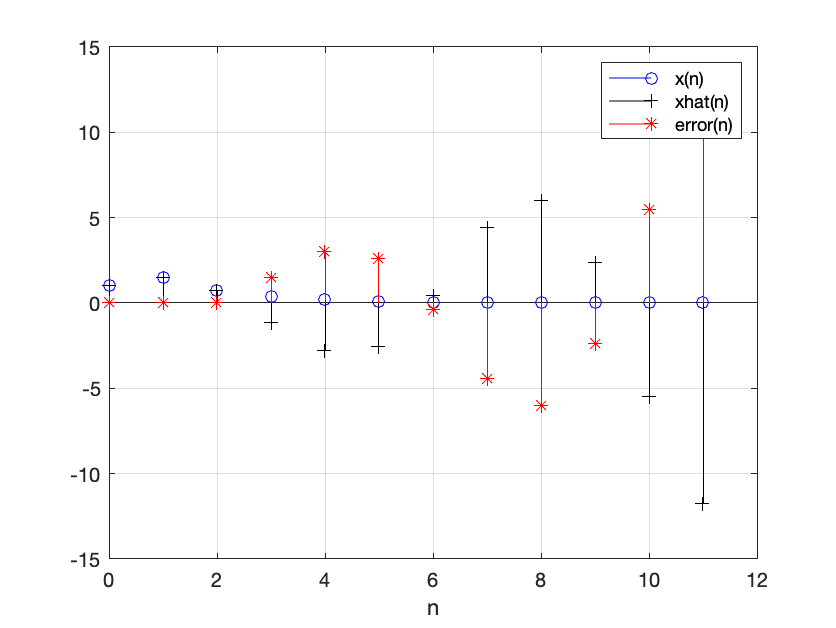


figure;
stem(n, xn, 'bo')
hold on
stem(n, xhat, 'k+')
stem(n, xn-xhat, 'r*')
grid
xlabel('n')
legend('x(n)', 'xhat(n)', 'error(n)')

## b) Test with MA(2) : p=0 and q=2 

In this case the solution for $b_q(n)$ is obvious because $h(n)=b_q(n)$ so $b_q(n) = x(n)$ :

q = 2;
p = 0;
bqma = xn(1:q+1)

bqma =     1.0000
    1.5000
    0.7500


apma = 1

apma = 1

xhatma = impz(bqma, apma, length(xn))

xhatma =     1.0000
    1.5000
    0.7500
         0
         0
         0
         0
         0
         0
         0


Elsma = norm(xhatma-xn)

Elsma = 0.4330

%Elsma = sqrt(sum((xhatma-xn).^2)) % same result

## Test with ARMA(1,1) : p=1 and q=1

In this case we need to solve with 2 step algorithm first we compute the $a_p$ coeff as in point a)

q=1;
p=1;
Xq = X(q+2:q+p+1, 2:p+1)

Xq = 1.5000

Compute the vector $x_{q+1}$ as well:

xq_1 = X(q+2:q+p+1, 1)

xq_1 = 0.7500

if det(Xq)
    ap_arma = inv(Xq)*(-xq_1); % pinv is used in case
    ap_arma = [1; ap_arma]
else
    disp('Xq is a singular matrix !')
end 

ap_arma =     1.0000
   -0.5000


Next we apply the step 2 and compute the $b_q$ coefficients:

X0 = X(1:q+1, 1:p+1)

X0 =     1.0000         0
    1.5000    1.0000


bq_arma = X0*ap_arma

bq_arma =      1
     1


The transfer function H(z) is:

xhat_arma = impz(bq_arma, ap_arma, length(xn))

xhat_arma =     1.0000
    1.5000
    0.7500
    0.3750
    0.1875
    0.0938
    0.0469
    0.0234
    0.0117
    0.0059


Els_arma = norm(xhat_arma-xn)

Els_arma = 0

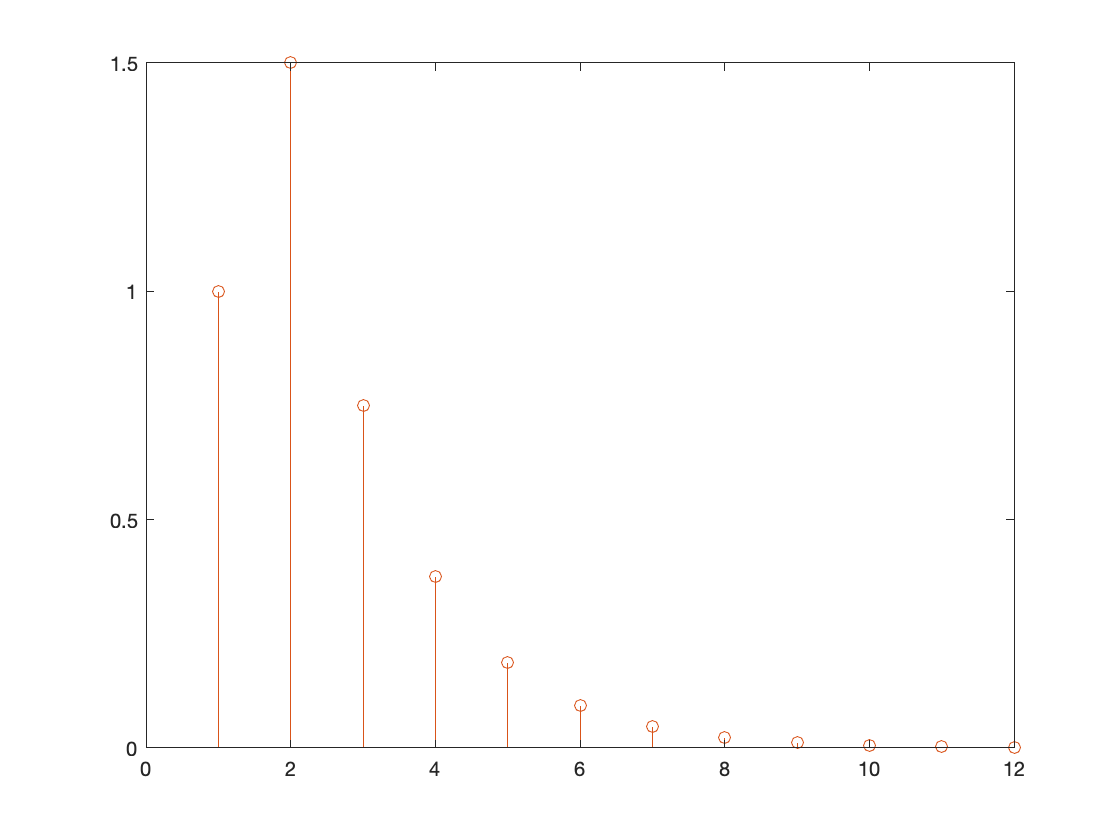


figure;
stem(xhat_arma)
hold on
stem(xn)

## Ex 4.3.3 : Singular example

Digital filter approximation

x2 = [1 4 2 1 3];
p = 2;
q = 2;

Compute the pade approximation with the pade function:

%[ap, bq, Els, xhat] = pade(x2, p, q); % Error Xq is a singular matrix

The Xq matrix is singular in this case!

That means the assumption that $ap(0) = 1$ is incorrect for this model so we put it to 0.

## Ex 4.3.4 : Filter design using the Padé approximation

The problem of the filter approximation is to find the impulse response $h(n)$ of the filter from a frequency constraints. For this example, to be as simple as possible we want to synthetize a filter with a frequency response $|H(jf)| = 1$ for $f<F_p$ and 0 for $F_p<f<0.5$.

Additionaly we want a linear phase response then $H(jf) = e^{jn_d2\pi f}$ for $f<F_p$ and $0$ for $F_p<f<0.5$, the constant $n_d$ is the time delay of the filter to assure the causality of it.


$$H(jf) = \begin{cases}e^{jn_d2\pi f} \; ; |f| < 0.25 \\ 0 \qquad ; \text{otherwise}
\end{cases}$$
 

Since the frequency response is a rectangular function the inverse transform is a sinc function of the variable $n$, the impulse response is:


$$h(n) = \frac{\sin[(n-n_d)\pi/2]}{(n-n_d)\pi}$$
 

With the function sinc we write it as: $h_n = \frac{1}{2} \cdot \text{sinc}((n-n_d)\cdot 2 \cdot F_p)$

N = 100;
Fp = 0.25;
n = 0:N-1;
nd = 5;

hn = 1/2 * sinc((n-nd)*2*Fp)

hn =     0.0637   -0.0000   -0.1061    0.0000    0.3183    0.5000    0.3183    0.0000   -0.1061   -0.0000    0.0637    0.0000   -0.0455   -0.0000    0.0354    0.0000   -0.0289   -0.0000    0.0245    0.0000   -0.0212   -0.0000    0.0187    0.0000   -0.0168   -0.0000    0.0152    0.0000   -0.0138   -0.0000    0.0127   -0.0000   -0.0118   -0.0000    0.0110    0.0000   -0.0103   -0.0000    0.0096   -0.0000   -0.0091   -0.0000    0.0086    0.0000   -0.0082   -0.0000    0.0078   -0.0000   -0.0074   -0.0000


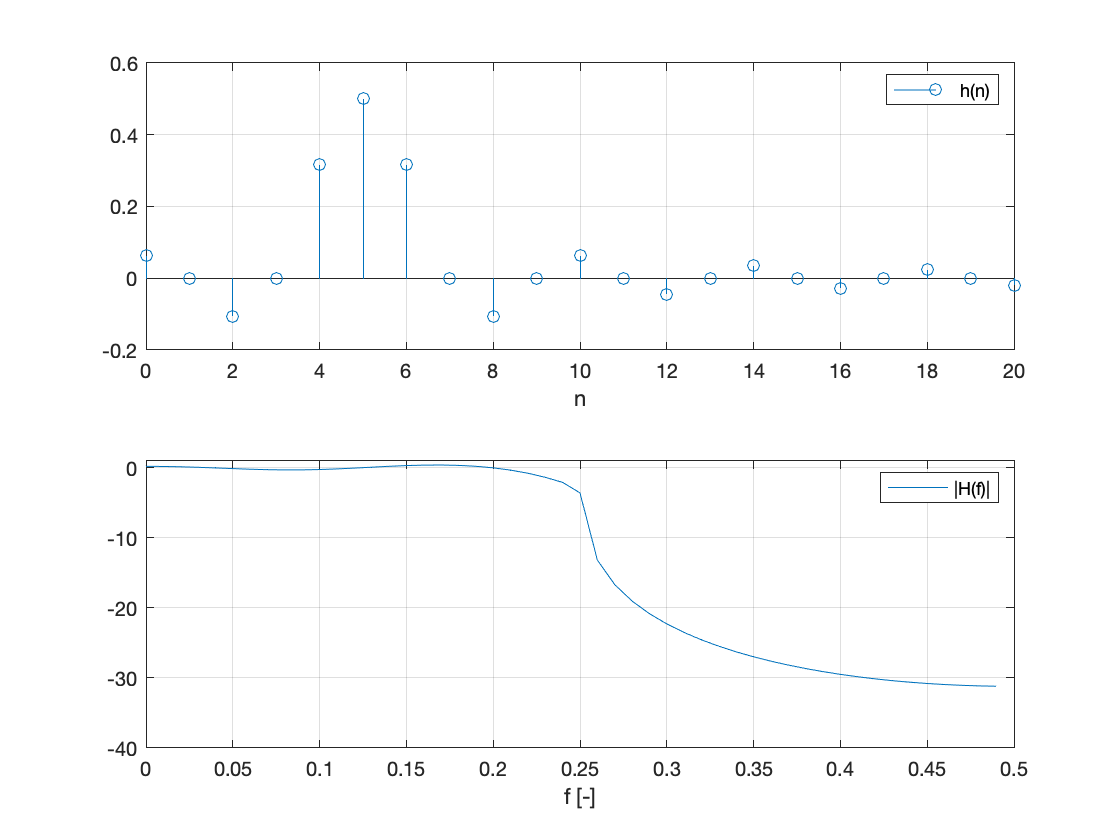


H = fftshift(fft(hn));
f = -0.5:1/N:0.5-0.5/N;

figure;
subplot(2,1,1)
stem(n,hn)
axis([0,20,-0.2,0.6])
grid;
xlabel('n')
legend('h(n)')
subplot(2,1,2)
plot(f,20*log10(abs(H)))
axis([0,0.5,-40,1])
grid;
xlabel('f [-]')
legend('|H(f)|')

If we design a FIR filter with $q=10$ and $p=0$ (MA) the Padé approximation will give the first 11 values of the $h(n)$. In this case $b_q(n) = h(n)$ for $n=0\dots 10$ 

p = 0;
q = 10;
[apFIR, bqFIR] = pade(hn, p, q);
apFIR'

ans = 1

bqFIR'

ans =     0.0637   -0.0000   -0.1061    0.0000    0.3183    0.5000    0.3183    0.0000   -0.1061   -0.0000    0.0637


We could plot the frequency response of this filter with the function `freqz():`

[H_FIR,F_FIR] = freqz(bqFIR, apFIR, N);

figure
plot(F_FIR*0.17, 20*log10(abs(H_FIR)))
hold on
plot(f, 20*log10(abs(H)))
axis([0,0.5,-40,1])

We want to find the transfer function of an ARMA system with $p=6$ and $q=6$:

p=6;
q=6;
[apIIR, bqIIR, ElsIIR] = pade(hn, p, q);
apIIR'

ans =     1.0000   -2.5171    3.9055   -4.0872    2.9647   -1.4088    0.3500


bqIIR'

ans =     0.0637   -0.1602    0.1425    0.0069    0.0927    0.0428    0.0106


ElsIIR

ElsIIR = 0.1365

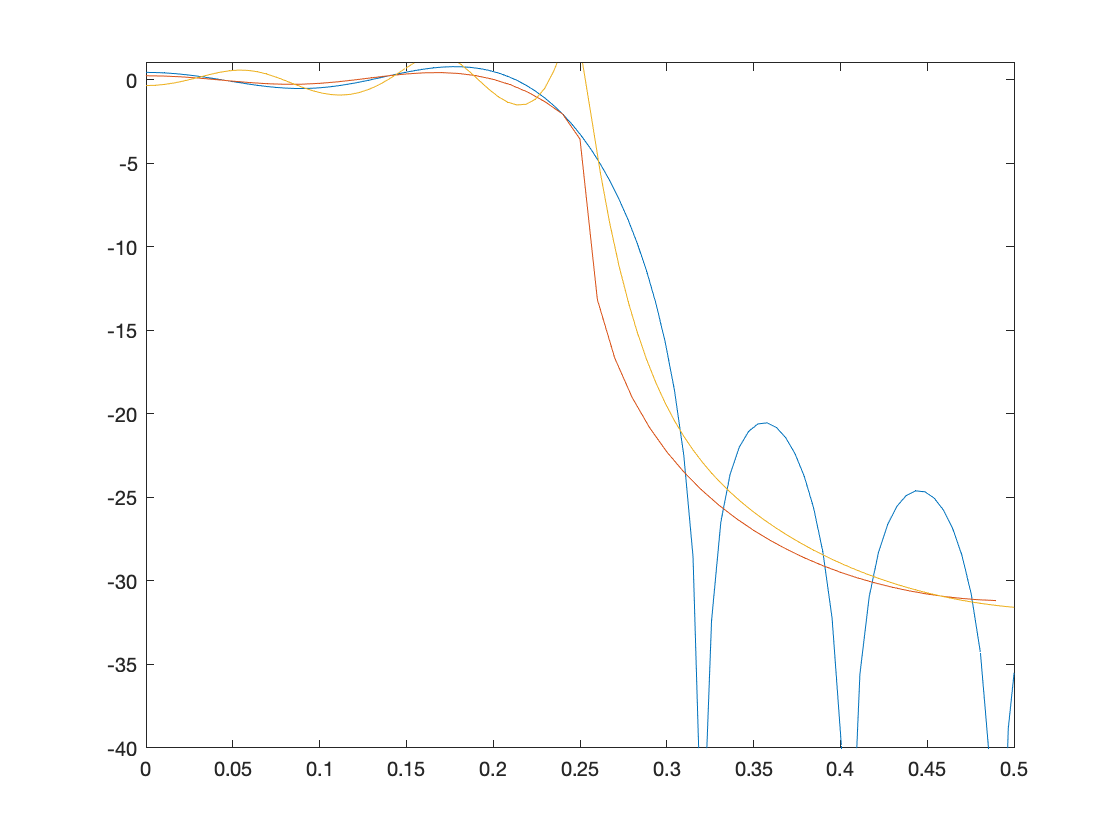


[H_IIR,F_IIR] = freqz(bqIIR, apIIR, N);

plot(F_IIR*0.17, 20*log10(abs(H_IIR)))

Compute the impulse responseof this filter over the $N$ samples and compare to the original impulse response $h(n)$:

hiir = impz(bqIIR, apIIR, N)

hiir =     0.0637
   -0.0000
   -0.1061
         0
    0.3183
    0.5000
    0.3183
    0.0000
   -0.1061
    0.0000


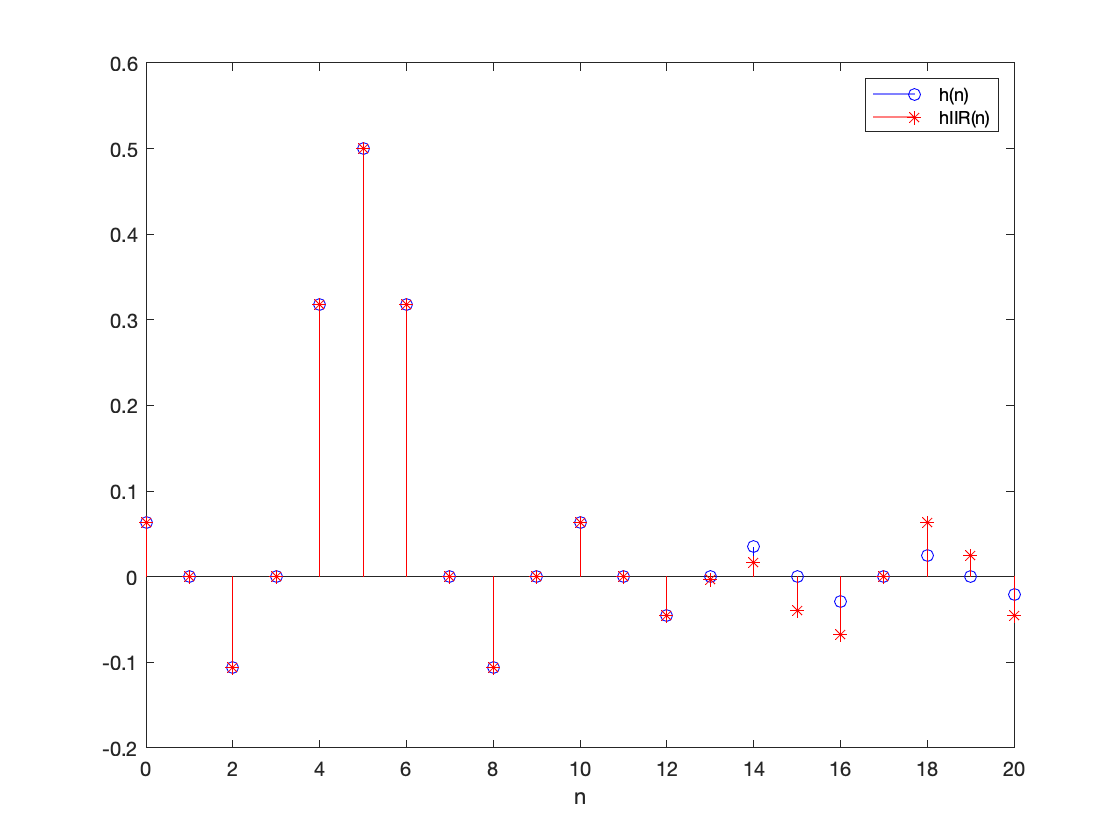


figure
stem(n, hn, 'bo')
hold on
stem(n, hiir, 'r*')
xlabel('n')
legend('h(n)', 'hIIR(n)')
axis([0,20,-0.2,0.6])